clear all;
%close all;
F = 5/2;
sigmax=spinOp(F,'x');
sigmay=spinOp(F,'y');
sigmaz=spinOp(F,'z');
initial = zeros(2*F+1,1);
initial(1) = 1;
%initial=spin_coherent(pi/2,pi/2);

fROT = 500;
ROT = fROT*(sigmax-1/8*sigmax^2);
fB = 12/5;
Bz = fB*sigmaz;
ROT_B = ROT+1*Bz;

phi1 = 3*pi;
tau1 = phi1/(2*pi*fROT);
state = ham_evolve(ROT_B,initial,tau1);

phi2 = atan(sqrt(3)/2);
tau2 = phi2/(2*pi*fB);
state = ham_evolve(Bz,state,tau2);

phi3 = 3*pi;
tau3 = phi3/(2*pi*fROT);
state = ham_evolve(ROT_B,state,tau3);

phi4 = pi/2;
tau4 = phi4/(2*pi*fB);
state = ham_evolve(Bz,state,tau4);

phi5 = 4*pi;
tau5 = phi5/(2*pi*fROT);
state = ham_evolve(ROT_B,state,tau5);

state1 = conj(state).*state;


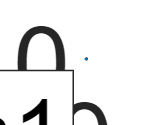


timelist=[0:0.01:4].*pi;
ham = 1*sigmax-1*sigmax^2+0*sigmaz;
%ham=3.7944*sigmax+0.46524*sigmax^2;
%ham=sigmay^2;

for i=1:length(timelist)
    time=timelist(i);
    finalstate(i,:)=ham_evolve(ham,initial,time);
end

figure;
for j=1:1
    plot(timelist,abs(finalstate(:,j)).^2,'LineWidth',2);
    hold on;
end
ylim([0 1]);
legend;
%set(gcf,'visible','on')
set(gca,'fontsize',35)

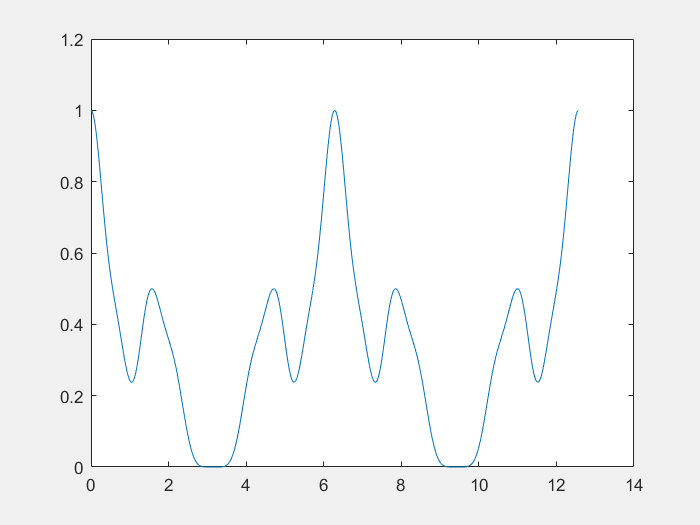

%phase=(abs(finalstate(:,1)).^2-abs(finalstate(:,6)).^2)...
%    ./(abs(finalstate(:,1)).^2+abs(finalstate(:,6)).^2);
phase=abs(finalstate(:,1)).^2;
figure;
plot(timelist,phase);
set(gcf,'Visible','on');

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
function state=spin_coherent(theta,phi)
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
polar=[1 0 0 0 0 0]';
state1=ham_evolve(sigmay,polar,theta);
state=ham_evolve(sigmaz,state1,phi);
end